clc
clear

n=50

n = 50

K=6

K = 6

L=10

L = 10


m1=15;
m=[m1 m1+L m1+(2*L) m1+(3*L) m1+(4*L) m1+(5*L)]

m =     15    25    35    45    55    65


marca=m';


f=[2;10;12;14;9;3];
fr=f/n;
F=cumsum(f);
Fr=F/n;
table(marca,f,F,fr,Fr)

ans = 6×5 table
    marca    f     F      fr      Fr 
    _____    __    __    ____    ____

     15       2     2    0.04    0.04
     25      10    12     0.2    0.24
     35      12    24    0.24    0.48
     45      14    38    0.28    0.76
     55       9    47    0.18    0.94
     65       3    50    0.06       1


mein=0

mein = 0

for i=1:K
    mein=mein+(m(i)*f(i));
end
media=mein/n;  

varin=0

varin = 0

for i=1:K
    varin=varin+(f(i)*((m(i)-media)^2));
end
varianza=varin/(n-1);

desviacion=sqrt(varianza);



me=['Media=',num2str(media)];
var=['Varianza=',num2str(varianza)];
des=['Desviacion=',num2str(desviacion)];
disp(me);

Media=40.4


disp(var);

Varianza=164.1224


disp(des);

Desviacion=12.811


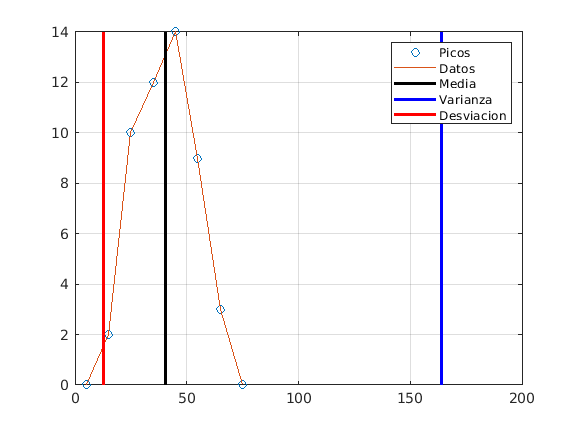



intervalo=[10:10:70];

%poligono
f=[2,10,12,14,9,3];
mp=[5 m 75];
fp=[0 f 0];
figure
plot(mp,fp,'o',mp,fp)
grid on
hold on
plot([media media],[0 14],'black','LineWidth',2)
plot([varianza varianza],[0 14],'b','LineWidth',2)
plot([desviacion desviacion],[0 14],'r','LineWidth',2)
legend('Picos','Datos','Media', 'Varianza','Desviacion') 
hold off






d1=0.1*n;
d1v=20+((((n/10)-2)/(10))*10);
d2=0.2*n;
d2v=20+((((n/10)-2)/(10))*10);
d5=0.5*n;
d5v=40+((((n/10)-24)/(14))*10);
d7=0.7*n;
d7v=40+((((n/10)-24)/(14))*10);
d1vv=['D1=',num2str(d1v)];
d2vv=['D2=',num2str(d2v)];
d5vv=['D3=',num2str(d5v)];
d7vv=['D7=',num2str(d7v)];
disp(d1vv);

D1=23


disp(d2vv);

D2=23


disp(d5vv);

D3=26.4286


disp(d7vv);

D7=26.4286


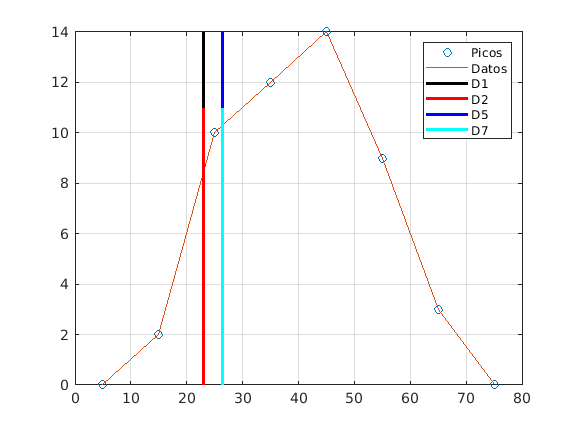

%poligono
f=[2,10,12,14,9,3];
mp=[5 m 75];
fp=[0 f 0];
figure
plot(mp,fp,'o',mp,fp)
grid on
hold on
plot([d1v d1v],[0 14],'k','LineWidth',2)
plot([d2v d2v],[0 11],'r','LineWidth',2)
plot([d5v d5v],[0 14],'b','LineWidth',2)
plot([d7v d7v],[0 11],'c','LineWidth',2)
legend('Picos','Datos','D1', 'D2','D5','D7') 
hold off



q1=0.25*n;
q1v=30+((((n/4)-12)/(12))*10);
q2=0.5*n;
q2v=40+((((n/4)-24)/(14))*10);
q3=0.75*n;
q3v=40+((((n/4)-24)/(14))*10);
q1vv=['Q1=',num2str(q1v)];
q2vv=['Q2=',num2str(q2v)];
q3vv=['Q3=',num2str(q3v)];
disp(q1vv);

Q1=30.4167


disp(q2vv);

Q2=31.7857


disp(q3vv);

Q3=31.7857


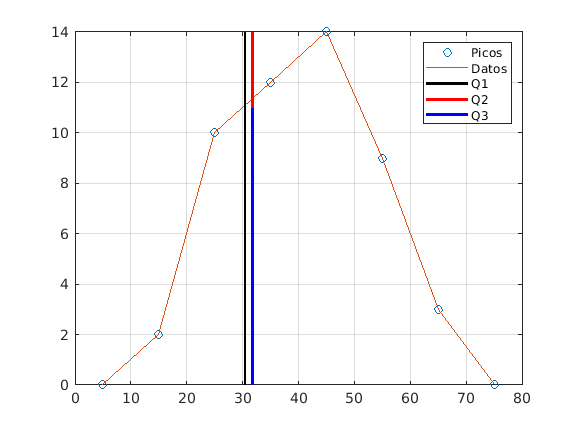

%poligono
f=[2,10,12,14,9,3];
mp=[5 m 75];
fp=[0 f 0];
figure
plot(mp,fp,'o',mp,fp)
grid on
hold on
plot([q1v q1v],[0 14],'k','LineWidth',2)
plot([q2v q2v],[0 14],'r','LineWidth',2)
plot([q3v q3v],[0 11],'b','LineWidth',2)
legend('Picos','Datos','Q1', 'Q2','Q3') 
hold off